A partir de las rutas sugeridas se seleccionó la ruta rectangular con esquinas curvas, de acuerdo al gráfico de la siguiente figura se crea la trayectoria a trozos en un plano XY que posteriormente será rotado y transladado al espacio de trabajo del robot.

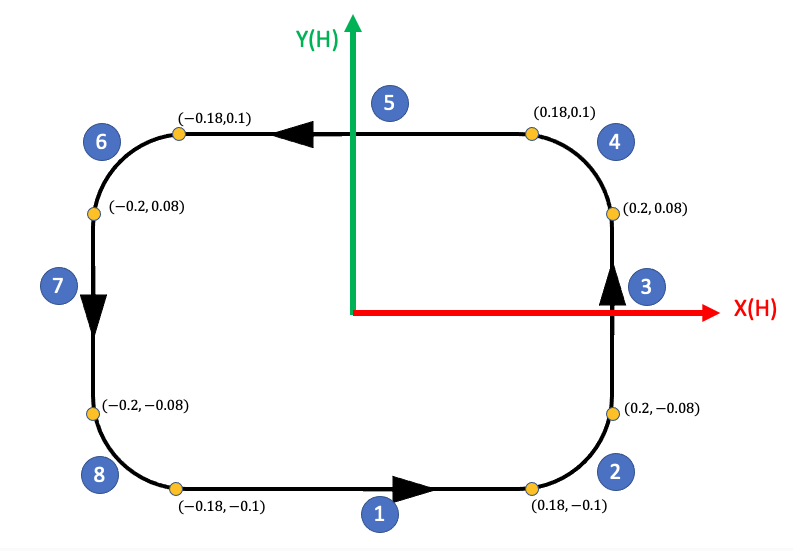

clc;clear;close all

Como se ve en la figura anterior, las coordenadas de la trayectoria son función del alcance horizontal del robot. Para el robot que se analizará en el presente trabajo el alcance horizontal (H) es igual a 700mm. Para poder escalar la trayectoria basta con multiplicar los parámetros de la misma por el alcance H como se muestra a continuación.

H=700;
a = 0.18*H; %distancia en x
b = 0.1*H;  %distancia en y
c = 0.08*H; %centro en y de los semicirculos
r = 0.02*H; %radio 

La trayectoria fue generada por segmentos de curvas y rectas concatenados entre sí comenzando en la coordenada (-0.18,-0.1) en sentido horario como se muestra a continuación.

%%Ruta 1
x = -a:0.01:a;
len = size(x);
y = -b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = R1;

figure()
plot(x,y);
hold on

%%Ruta 2
t = 3*pi/2:pi/20:2*pi;
x = r*cos(t)+a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 3
y = -c:0.01:c;
len = size(y);
x = (a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 4
t = 0:pi/20:pi/2;
x = r*cos(t)+a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 5
x = a:-0.01:-a;
len = size(x);
y = b*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 6
t = pi/2:pi/20:pi;
x = r*cos(t)-a;
y = r*sin(t)+c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 7
y = c:-0.01:-c;
len = size(y);
x = -(a+r)*ones(len);
z = zeros(len);
R1 = [x;y;z];
traye = [traye,R1];
plot(x,y);

%%Ruta 8
t = pi:pi/20:3*pi/2;
x = r*cos(t)-a;
y = r*sin(t)-c;
len = size(x);
z = zeros(len);
R1 = [x;y;z];

traye = [traye,R1];
plot(x,y);
hold off

La trayectoria elegida debe realizarse en el plano asignado para este ejercicio. En este caso particular, el plano debe ser perpendicular al vector [-1,0,1]. Para rotar la trayectoria se crea una matriz de rotación la cual permita obtener la orientación deseada.

%Matriz de Rotacion
R = [1/sqrt(2),0,-1/sqrt(2);
     0        ,1,0         ;
     1/sqrt(2),0, 1/sqrt(2)];

Finalmente se dejan enunciados los parámetros de desplazamiento de la trayectoria para posteriormente poder ubicarla en el espacio diestro del robot como se solicitó.

% Desplazamiento
x = 0;
y = 0;
z = 0;

%% Rotacion y dezplazamiento de la trayectoria

len = size(traye);
for i = 1:len(2)
    traye(1:3,i) = R*traye(1:3,i);
end

traye(1,:) = x + traye(1,:);
traye(2,:) = y + traye(2,:);
traye(3,:) = z + traye(3,:);

figure
plot3(traye(1,:),traye(2,:),traye(3,:))
grid on
view([142 47])